# **Projet DMLV : A new approach to model regime switching**

clc ; clear ; clear all;
global endog;

## First part - Application of the algorithm on Hamilton's data

### Importation of data and visualization

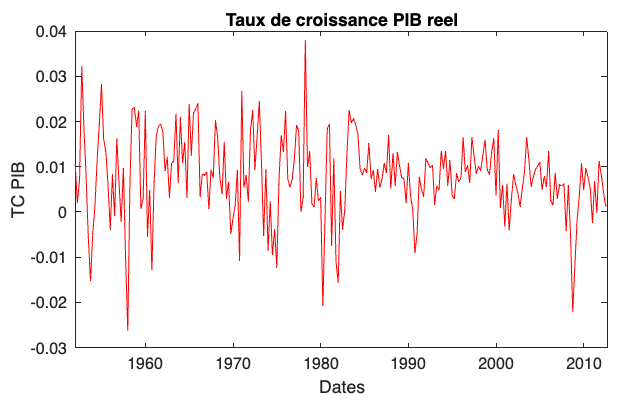

% Data imports
data_gdp = readtable("Data/GDP US.xlsx", "Sheet","Quarterly");
dates = data_gdp.observation_date;
gdp = data_gdp.GDPC1;

% Computation of logarithm and growth rate
log_gdp = log(gdp);
growth_gdp = diff(log_gdp, 1);
dates_growth_gdp = dates(2:length(dates));

% Sampling to keep the same period as paper (endogenous variable)
index_backtest = dates_growth_gdp >= '01-Jan-1952' & dates_growth_gdp <= '01-Oct-2012';
endog = growth_gdp(index_backtest);

% Data vizualisation
f0 = figure("Units","normalized","Position",[0 0 1 1]);
t = tiledlayout(1,1,'TileSpacing','compact','Padding','compact');
nexttile();
plot(dates_growth_gdp(index_backtest), endog, 'r');title("Taux de croissance PIB reel");
xlabel("Dates");ylabel("TC PIB");

### Fit of an AR(4) model in the linear case 

% Number of observation
T = length(endog);

% Number of lags considered for the model
p = 4;

% Creation of a constant vector
X = ones(T - p,1);

% Vector of endogenous variables to fit the AR(4) (benchmark for the
% initial coefficients)
Y = endog((1+p):end);

% Costruction of covariates vector
for i=1:p
    X(:, end+1) = endog(p-i+1:T-i);
end

% Computation of AR coefficients
phi = inv(X'*X) * (X'*Y);

% Usual significativity tests (optional)
e = Y - X*phi;
vare = (e'*e)/(length(e)-1);

% Computation of variance-covariance matrix for coef
omega = vare * inv(X'*X);

% Student test
t = phi./sqrt(diag(omega));
pval = 2*(1-normcdf(abs(t)));
param_est = [phi  sqrt(diag(omega))  t  pval];
disp(array2table(param_est, "RowNames",{'const','phi1','phi2', 'phi3', 'phi4'},'VariableNames',{'Coefs','Standard errors', 'T-stat', 'Pvalue'}));

               Coefs      Standard errors     T-stat       Pvalue  
             _________    _______________    ________    __________

    const    0.0050365      0.00088498         5.6911    1.2621e-08
    phi1       0.32141        0.063416         5.0683    4.0146e-07
    phi2       0.14425         0.06642         2.1717      0.029878
    phi3     -0.097517        0.066337          -1.47       0.14156
    phi4     -0.039385        0.063397       -0.62125       0.53443



### Likelihood maximization

% We retrieve the coefficients for the AR coefficients (initial guess)
arcoefs = phi(2:end);

% Initial values for the other parameters (arbitrary)
mu = [phi(1)*0.5 ; phi(1)*1.5]; sigma = [0.8 ; 0.4];
tau = 1.2; 
alpha = 0.8;
rho = 0.7;
x0 = [mu' sigma' tau alpha rho arcoefs']';

% Computation of the likelihood for these parameters (debut at this point)
L = ms_threshold_filter(x0);

Unrecognized function or variable 'vecMu'.

Error in ms_threshold_filter (line 40)
nb_regimes = max(length(vecMu), length(vecSigma));


% Optimisation
% options = optimset('MaxIter',1000, 'TolFun', 10^-10, 'TolX',10^-10);
% [x, fval, code,  info, g, H] = fminunc(@ms_threshold_filter, x0);


## Deuxième partie - Simulations